bml_defaults

SUBJECT='DM1025';
SESSION = 'intraop';
TASK = 'lombard';
PATH_DATASET = 'Y:\DBS';

PATH_DER = [PATH_DATASET filesep 'derivatives'];
PATH_DER_SUB = [PATH_DER filesep 'sub-' SUBJECT];  
PATH_PREPROC = [PATH_DER_SUB filesep 'preproc'];
PATH_ANNOT = [PATH_DER_SUB filesep 'annot'];
PATH_FIELDTRIP = [PATH_DER_SUB filesep 'fieldtrip'];

PATH_FIG = [PATH_PREPROC '\figures'];

FNAME_BASE = ['sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_preproc']; 

% loading annotation tables
sessions = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_sessions.tsv']);

runs = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_runs.tsv']);
channels = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_channels.tsv']);
trials = bml_annot_read_tsv([PATH_ANNOT filesep 'sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_annot-trials.tsv']);

runs_task = runs(runs.task == string(TASK), :);

## Define rejection parameters

CRITERIA = 'A';
chs_oi = {'ecog_*'}; % channels of interest

HIGH_PASS_FILTER = 'yes'; %should a high pass filter be applied
HIGH_PASS_FILTER_FREQ = 1; %cutoff frequency of high pass filter

ECOG_ENVELOPE_BIN_SIZE_SECONDS = 1; %envelope bin size in seconds
ECOG_THRESHOLD_STD_FACTORS = [2, 3]; %factors to determine detection thresholds 
ECOG_CONSOLIDATION_TIME_TOLERANCE = 3; %min time allowed between adjacent artifacts
ELECTRODE_COVERAGE_THRESHOLD = 0.2; % max allowed fraction of time with artifacts
CONNECTOR_THRESHOLD = [4, 8]; % detection threshold for faulty electrodes in connector

## Load continuous FieldTrip data

load([PATH_FIELDTRIP filesep 'sub-' SUBJECT '_ses-' SESSION '_task-' TASK '_ft-raw.mat'],'D');
n_trials = numel(D.trial);

## Remove nans

cfg=[];
cfg.value = 0;
cfg.remask_nan = true;
D_mask = bml_mask(cfg,D); % ERROR with istrue()

## high pass filtering

cfg=[];
cfg.hpfilter=HIGH_PASS_FILTER;	 % setting a high pass filter
cfg.hpfreq=HIGH_PASS_FILTER_FREQ; % 1Hz cutoff frequency	
cfg.hpfilttype='but';    		 % using butterworth filter
cfg.hpfiltord=5;         		 % of order 5
cfg.hpfiltdir='twopass'; 		 % two passes not to introduce time shift
cfg.channel=chs_oi; %include channels to filter
D_hpf = ft_preprocessing(cfg,D_mask);

> In fixsampleinfo (line 102)
In ft_datatype_raw (line 149)
In ft_checkdata (

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 4 from 4

the call to "ft_preprocessing" took 9 seconds




%notch filtering
freqs=[60 120 180 240];
cfg=[];
cfg.hpfilter='yes';
cfg.hpfreq=1;
cfg.hpfilttype='but';
cfg.hpfiltord=5;
cfg.hpfiltdir='twopass';
cfg.bsfilter='yes';
cfg.bsfreq= [freqs-1; freqs+1]';
D_notch = ft_preprocessing(cfg,D_hpf);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 4 from 4

the call to "ft_preprocessing" took 41 seconds



D_hpf_chsoi = D_notch;

## Visualize with FieldTrip

UNCOMMENT if stepping through this manually 



idxs_ecog_geometric = reshape(1:63, [21, 3])'; 
idxs_ecog_geometric = idxs_ecog_geometric(:); 
idxs_ecog_geometric = [idxs_ecog_geometric; idxs_ecog_geometric+numel(idxs_ecog_geometric)]; 
idxs_ecog = startsWith(D_hpf_chsoi.label, 'ecog'); 
idxs_new = 1:length(D_hpf_chsoi.label); 
idxs_new(idxs_ecog) = idxs_ecog_geometric; 

% strip1 = "ecog_L1" + arrayfun(@(x) sprintf('%02d',x),  idxs_geometric,  'UniformOutput',  false);
% strip2 = "ecog_L2" + arrayfun(@(x) sprintf('%02d',x),  idxs_geometric,  'UniformOutput',  false);
% cfg = []; 
% cfg.channel = convertStringsToChars([strip1; strip2]); 
% cfg.channel = {'ecog_L2*', 'ecog_L1*'};
% cfg.channel = 10;
cfg.idxs = idxs_new;
Dtmp = bml_reorder_channels(cfg, D_hpf_chsoi);

% visualize Dtmp with 
bml_databrowser

## Calculate envelopes

cfg=[];
cfg.freq=ECOG_ENVELOPE_BIN_SIZE_SECONDS;
D_hpf_chsoi_env = bml_envelope_binabs(cfg, D_hpf_chsoi);
D_hpf_chsoi_env_log10 = bml_apply(@(x) log10(x), D_hpf_chsoi_env);

## Determine thresholds

THRESHOLD = nan(n_trials,2);
for i=1:n_trials
  v = reshape(D_hpf_chsoi_env_log10.trial{i},1,[]);
  m = nanmedian(v);
  std = bml_robust_std(v);
  THRESHOLD(i,:) = m + ECOG_THRESHOLD_STD_FACTORS.*std;
end

## Visualize histogram

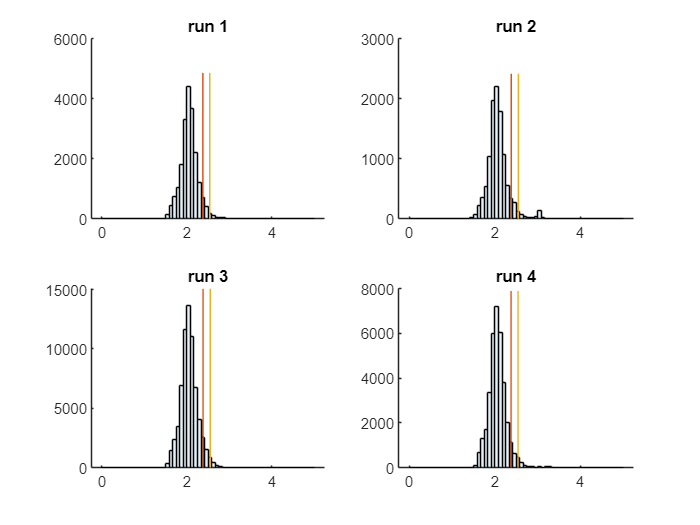

f=figure();
for i=1:n_trials
  subplot(ceil(n_trials/2),2,i)
  hold on;
  h=histogram(D_hpf_chsoi_env_log10.trial{i},linspace(0,5,61),...
'FaceAlpha',0.1,'EdgeAlpha',1);
  maxBinCount = max(h.BinCounts);
  plot([THRESHOLD(i,1),THRESHOLD(i,1)],[0,maxBinCount .* 1.1]);
  plot([THRESHOLD(i,2),THRESHOLD(i,2)],[0,maxBinCount .* 1.1]);
  title(['run ' num2str(i)]);
end

% saveas(f,['figures/' SUBJECT '_P08_ar_' CRITERIA '_hpf_ecog_env_log10_hist.png'])

## Detect segments of time for each channel above threshold, per run

artifact_chsoi_1 = table();
for i=1:n_trials
  cfg=[];
  cfg.threshold = THRESHOLD(i,:);
  cfg.trials = i;
  artifact_chsoi_1 = bml_annot_rowbind(artifact_chsoi_1,...
                                       bml_annot_detect(cfg,D_hpf_chsoi_env_log10));
end

Detecting trial 1, labels: 
ecog_L101 ecog_L102 ecog_L103 ecog_L104 ecog_L105 ecog_L106 ecog_L107 ecog_L108 ecog_L109 ecog_L110 
ecog_L111 ecog_L112 ecog_L113 ecog_L114 ecog_L115 ecog_L116 ecog_L117 ecog_L118 ecog_L119 ecog_L120 
ecog_L121 ecog_L122 ecog_L123 ecog_L124 ecog_L125 ecog_L126 ecog_L127 ecog_L128 ecog_L129 ecog_L130 
ecog_L131 ecog_L132 ecog_L133 ecog_L134 ecog_L135 ecog_L136 ecog_L137 ecog_L138 ecog_L139 ecog_L140 
ecog_L141 ecog_L142 ecog_L143 ecog_L144 ecog_L145 ecog_L146 ecog_L147 ecog_L148 ecog_L149 ecog_L150 
ecog_L151 ecog_L152 ecog_L153 ecog_L154 ecog_L155 ecog_L156 ecog_L157 ecog_L158 ecog_L159 ecog_L160 
ecog_L161 ecog_L162 ecog_L163 ecog_L201 ecog_L202 ecog_L203 ecog_L204 ecog_L205 ecog_L206 ecog_L207 
ecog_L208 ecog_L209 ecog_L210 ecog_L211 ecog_L212 ecog_L213 ecog_L214 ecog_L215 ecog_L216 ecog_L217 
ecog_L218 ecog_L219 ecog_L220 ecog_L221 ecog_L222 ecog_L223 ecog_L224 ecog_L225 ecog_L226 ecog_L227 
ecog_L228 ecog_L229 ecog_L230 ecog_L231 ecog_L232 ecog_L233 eco


artifact_chsoi_1 = renamevars(artifact_chsoi_1, 'label', 'ch_name');

% Consolidate instances within a certain time threshold of each other 
cfg=[];
cfg.criterion = @(x) (x.starts(end) - max(x.ends(1:(end-1))) < ECOG_CONSOLIDATION_TIME_TOLERANCE);
cfg.groupby = 'ch_name';
artifact_chsoi_2 = bml_annot_consolidate(cfg, artifact_chsoi_1);

## Visualize with raster plot

artifact_chsoi_3 = artifact_chsoi_2; 

cfg=[];
cfg.template = D_hpf_chsoi_env_log10;  	% ft_raw object to use as template
cfg.label_colname='ch_name';   		% what variable of the table to use as channel name 
artifact_chsoi_3_raw = bml_annot2raw(cfg, artifact_chsoi_3);

using labels from template


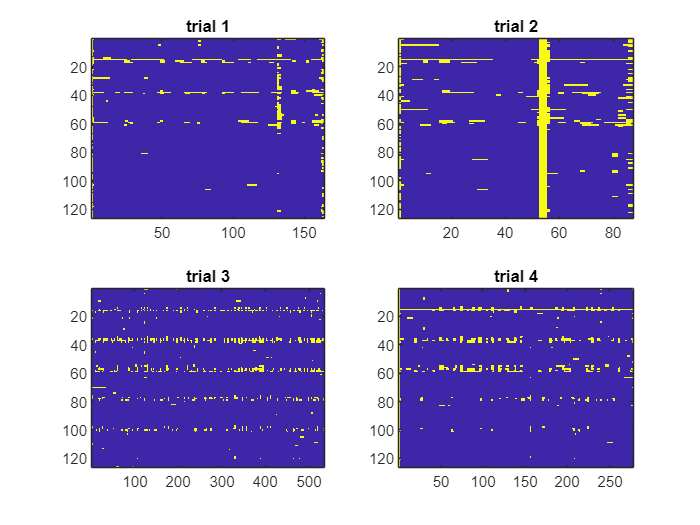


f=figure();
bml_plot_raster(artifact_chsoi_3_raw);

## Detect artifactual channels

Note: the function bml_annot_coverage implements a kind of "division" between annotation tables. For every row in session, it checks what fraction of that time interval coincides with rows in artifact_1. It does this grouping first by label, that means it will return one row per label per session. The returned object is an annotation table.

cfg = [];
cfg.groupby = 'ch_name';
artifact_1_session_cvg = bml_annot_coverage(cfg, artifact_chsoi_1, runs_task);

artifact_1_session_cvg_sel = artifact_1_session_cvg( ...
    artifact_1_session_cvg.coverage >= ELECTRODE_COVERAGE_THRESHOLD,:);

Reject selected "electrodes by sessions"

The easiest way of doing this, is combining the table 'artifact_1_session_cvg_sel ' with 'artifact_1' and then consolidating. Conceptually, we are making an union of both annotation tables, grouping by 'label'. 

cfg=[];
cfg.groupby = 'ch_name';
artifact_2 = bml_annot_union(cfg,artifact_chsoi_1, artifact_1_session_cvg_sel);

Make raster plot to visualize effect of rejecting entire electrode

%creating ft_raw from annotations for visualization
cfg=[];
cfg.template = D_hpf_chsoi_env;
cfg.label_colname='ch_name';
artifact2_raw = bml_annot2raw(cfg, artifact_2);

using labels from template



%raster plot of artifacts 
f=figure();
bml_plot_raster(artifact2_raw);

## Save annotation table

artifact = artifact_2(:,{'id','starts','ends','duration','ch_name','trial'});
artifact = renamevars(artifact, 'trial', 'run_id');
artifact = renamevars(artifact, 'ch_name', 'channel');
artifact.subject_id = repmat(SUBJECT, [height(artifact) 1]);
artifact.session_id = repmat(SESSION, [height(artifact) 1]);
artifact.task_id = repmat(TASK, [height(artifact) 1]);

bml_annot_write_tsv(artifact, [PATH_ANNOT filesep bml_bids_basefname(SUBJECT, SESSION, TASK) '_artifact-criteria-' CRITERIA '.tsv']);
